# Calcolo errore con divisore di tensione con Opamp

Importo i dati reali presi con l'ADC dell'arduino

load dati.csv

Plotto i dati appena acquisiti

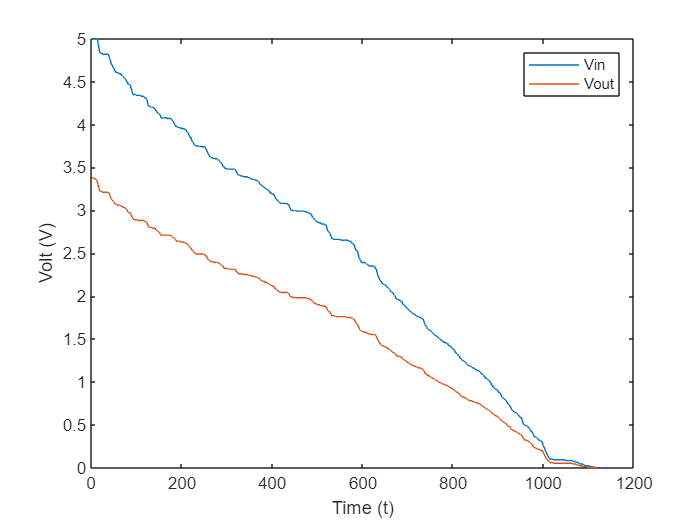

plot(dati);
xlabel("Time (t)");
ylabel("Volt (V)");
legend("Vin","Vout");

Definisco le costanti:

- Vin `e la tensione in uscita dal sensore di corrente 

- Vout `e la tensione rapportata al fattore di scala in uscita dal divisore di tensione, 

- Kp e Ka sono rispettivamente il fattore di scala del divisore e la sensibilit`a del sensore di corrente.

Vin = dati(:,1);
Vout = dati(:,2);
Kp = 2/3;   % ovvero 3.3V/5V
Ka = 0.4;

## Calcolo l'errore in Vout

Calcolo la tensione di uscita dal divisore di tensione IdealVout

IdealVout = Vin * Kp;

Calcolo l'errore per gni valore del mio vettore sottraendo al valore reale il valore ideale

erroreVout = IdealVout - Vout;

Calcolo il modulo del vettore e ne calcolo l'errore medio

erroreVout = abs(erroreVout);
mediaErroreVout = mean(erroreVout);    
disp("Errore in Vout = " +  mediaErroreVout)

Errore in Vout = 0.0080978


## Calcolo l'errore in Vin

Calcolo la tensione in entrata dal divisore di tensione IdealVin 

IdealVin = Vout / Kp;

Calcolo l'errore per gni valore del mio vettore sottraendo al valore ideale il valore reale

erroreVin = IdealVin - Vin;

Calcolo il modulo del vettore e ne calcolo l'errore medio

erroreVin = abs(erroreVin);
mediaErroreVin = mean(erroreVin);    
disp("Errore in Vin = " +  mediaErroreVin)

Errore in Vin = 0.012147


## Calcolo l'errore in ampeare sull'errore medio della Vin

erroreAmpeare = mediaErroreVin / Ka;
disp("Errore in Ampeare = " +  erroreAmpeare)

Errore in Ampeare = 0.030367
